# `Numerical Derivatives Group Assignment`

#### `Bethany Wu & Alex Stapely`

## `Problem 1: Finite Differences`

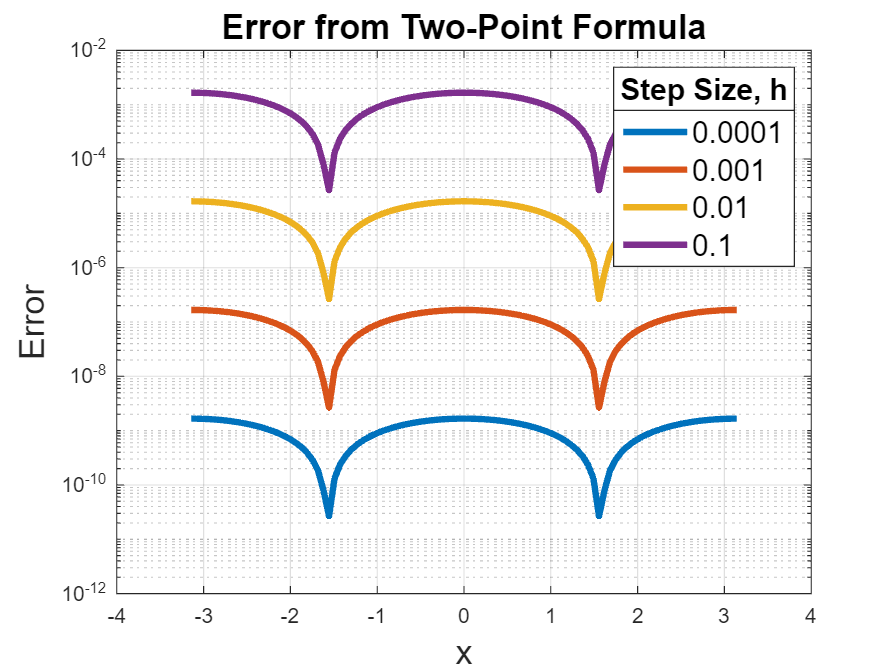

syms x0 h0
x = linspace(-pi,pi,100);
y = @sin;
dydx = @(x0,h0)  (y(x0+h0)-y(x0-h0))/(2*h0);

hs = [0.0001 0.001 0.01 0.1];
figure();
for h = hs
    yp = dydx(x,h);
    semilogy(x,abs(yp-cos(x)),'LineWidth',3); hold on;
end
title('Error from Two-Point Formula','FontSize',16); xlabel('x','FontSize',16); ylabel('Error','FontSize',16);
leg = legend(string(hs),'FontSize',14); title(leg,'Step Size, h'); grid on; hold off;

`Looking at the error plot, as h is decreased by an order of magnitude, the overall error of the derivative using the two-point formula us decreased by TWO orders of magnitude! When h = 1e-4, the error is in the range 1e-11 to 1e-9.`

## `Problem 2: More sophisticated derivatives...`

### `Part (a)`

`Richardson extrapolation of the finite difference formulas: Alex`

%Example use of Richardson extrapolation
f=@(x) sin(x);
% x = Point(s) to evaluate at
x = pi;
% Step
h = 0.4;
% Order of extrapolation 
n = 4;
[result, der, h] = richardson(f,x,h,n);
% Prints Result
fprintf('According to the Richardson extrapolation method, the derivative is: %.9f\n', der);

According to the Richardson extrapolation method, the derivative is: -0.999999998


`AD using dual numbers:`

`Chebyshev methods:`

## `Part (b)`

## `Part (c)`

## `Part (d)`

# `Functions`

function [R, der, h]  = richardson(f, x, h, n)
    R(1,1) = (f(x+h)-f(x))/h;
    for i = 1:n
        h = h/2;
        R(i+1,1)=(f(x+h)-f(x))/h;
        for j=1:i
            R(i+1,j+1)=(2^j*R(i+1,j)-R(i,j))/(2^j-1);
        end
    der = R(i+1,j+1);
    end
end